# MXB161 IW2 What size is that?

This is your Individual Worksheet (IW).  Complete this worksheet at your own pace.  After you've completed the worksheet, you'll be ready to take the Quiz for this topic, which can be found on Canvas on the Topic 2 - What size is that? page.

## Getting started

This worksheet is designed to be completed in conjunction with the associated online lecture on Canvas.

If you haven't yet started the online lecture, please start that first.  You'll be directed to return to this worksheet at the appropriate time in the lecture.

## 2.1 Plotting and joining points on maps

Here are the latitute and longitude coordinates of seven sporting venues around Brisbane.  For the benefit of the International Olympic Committee we'd like to plot these locations as points on a figure -- i.e. to make a little map.

We can convert these to $(x,y)$ coordinates using QUT Gardens Point as the origin. The calculations required are covered in worksheet GW1, and you don't need to recall the details for this worksheet.  Here, we just present the result for these locations.

venues_x = [-1.8265    0.9363   -1.0075    3.3735   -1.9844   11.7901    4.1628]; % x coordinates of venues relative to QUT
venues_y = [ 1.3581   -0.9557    3.9167   -9.0317   -5.3497   -3.7812   15.0184]; % y coordinates of venues relative to QUT

Now we might like to plot these locations, as well as the origin, on a new figure.  Enter the code to plot of each venue as a dot `'.'`, and the origin (0,0) as an `'x'`.  Refer back to the lecture video if you get stuck.

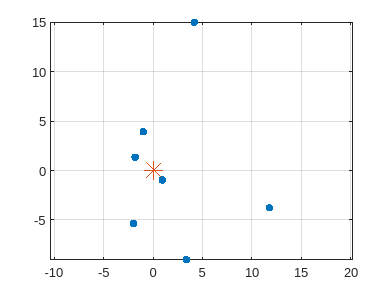

figure
plot(venues_x, venues_y, ".", MarkerSize=14)
hold on
plot(0, 0, "*", MarkerSize=14)
axis equal
grid on

We can also label all the venues in the figure.  The following command creates an array of names.

names = ["Lang Park", "Gabba", "Ballymore", "QE2", "Tennyson", "Chandler", "Boondall"]

names = 1×7 string array
    "Lang Park"    "Gabba"    "Ballymore"    "QE2"    "Tennyson"    "Chandler"    "Boondall"


Notice that we use double quotes for the strings, as explained in the lecture video.

Now label your points with the venue names.   Refer back to the lecture video if you get stuck.

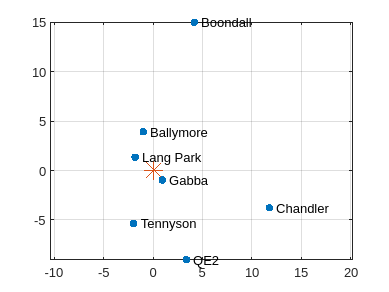

text(venues_x, venues_y, "  " + names);

Now enter the text command to label QUT, which is the origin (0,0) of this plot.

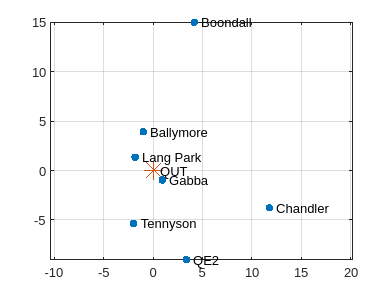

text(0, 0, "  QUT")

Suppose we want to draw lines connecting our origin, QUT, to each venue.  This step is slightly trickier to automate.  Essentially we need to cycle, or "loop", through each venue one by one, and draw the connecting line from QUT to each.  This is a perfect job for a `for` loop!

Write a `for` loop to connect the origin to each venue.  Refer back to the lecture video if you get stuck.

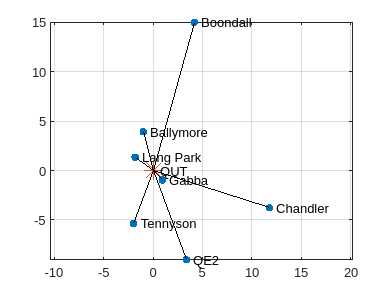

for i = 1:length(venues_x)
    plot([0, venues_x(i)], [0, venues_y(i)], 'k');
end

**Well done on finishing this section**.  Now you can return to the online lecture.

## 2.2 Animations with for loops

Recall the equations for a Lissajous curve:


$$x = \cos(a\pi t),\quad y = \sin(b\pi t)$$


Hopefully last week you worked out what values for $a$ and $b$ give the ABC logo.  If not -- go back to last week's lecture and experiment until you do!

This week we are going to animate the logo, in the style of the ABC promotion that ran on TV many years ago.  Start by copying your code from last week that made the interactive Lissajous figure.

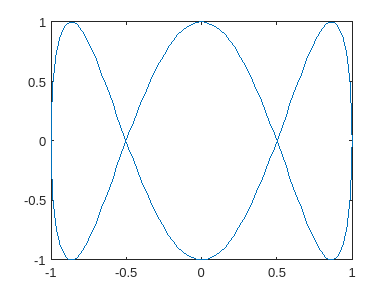

figure
a = 1;
b = 3;
x = sin(a * pi * t);
y = cos(b * pi * t);
plot(x, y)

Now you want to remove the slider code, and instead hard-code in the relevant values for $a$ and $b$.  You should have a figure like the following:

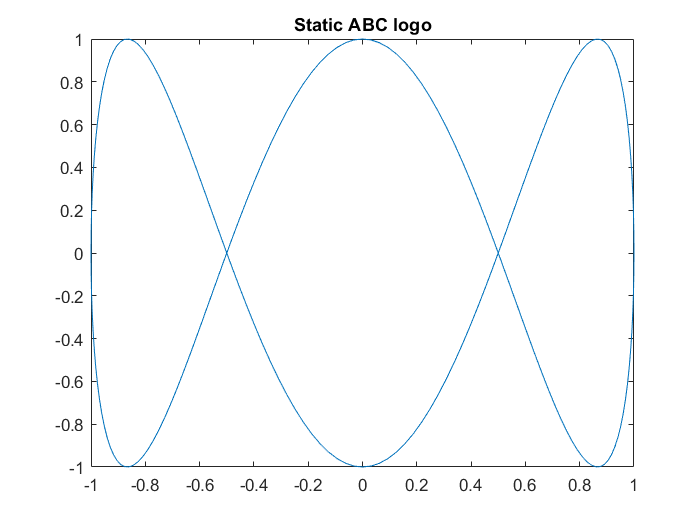

Now using the `for` loop technique demonstrated in the online lecture, turn this static figure into a lovely animation!  You have two options for making the animation:

- If you use `figure('visible', true)`, you'll get a new figure window open with a snappy animation.

- If you use `figure` alone, the animation will (painstakingly!) develop in the Live Script, but you'll get a control to replay or scrub back and forth once it's done.

Your choice!

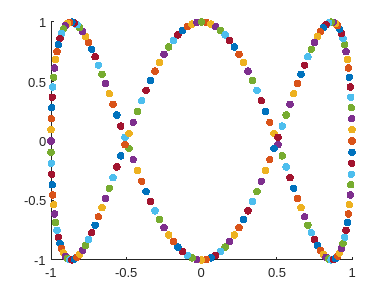

figure
t = 0:0.01:2;
a = 1;
b = 3;
x = sin(a * pi * t);
y = cos(b * pi * t);
hold on
for i = 1:length(y)
    plot(x(i), y(i), ".", MarkerSize=14)
    drawnow
end

**Well done on finishing this section**.  Now you can return to the online lecture.

## 2.3 Computing distances and areas from images

In this section we will look at an image of a fossilised resin canal from a scientific paper, *Christopher J Williams, Emily K Mendell, Jennifer Merphy, Arthue H Johnson, Suzanna L Richter, et al. Paleoenvironmental reconstruction of a middle miocene forest from the western canadian arctic. Palaeogeography, Palaeoclimatology, Palaeoecology, 261(1):160-176, 2008.*, and approximate the area of the resin canal in the image. First, we will load the JPEG image file using `imshow` into a new figure:

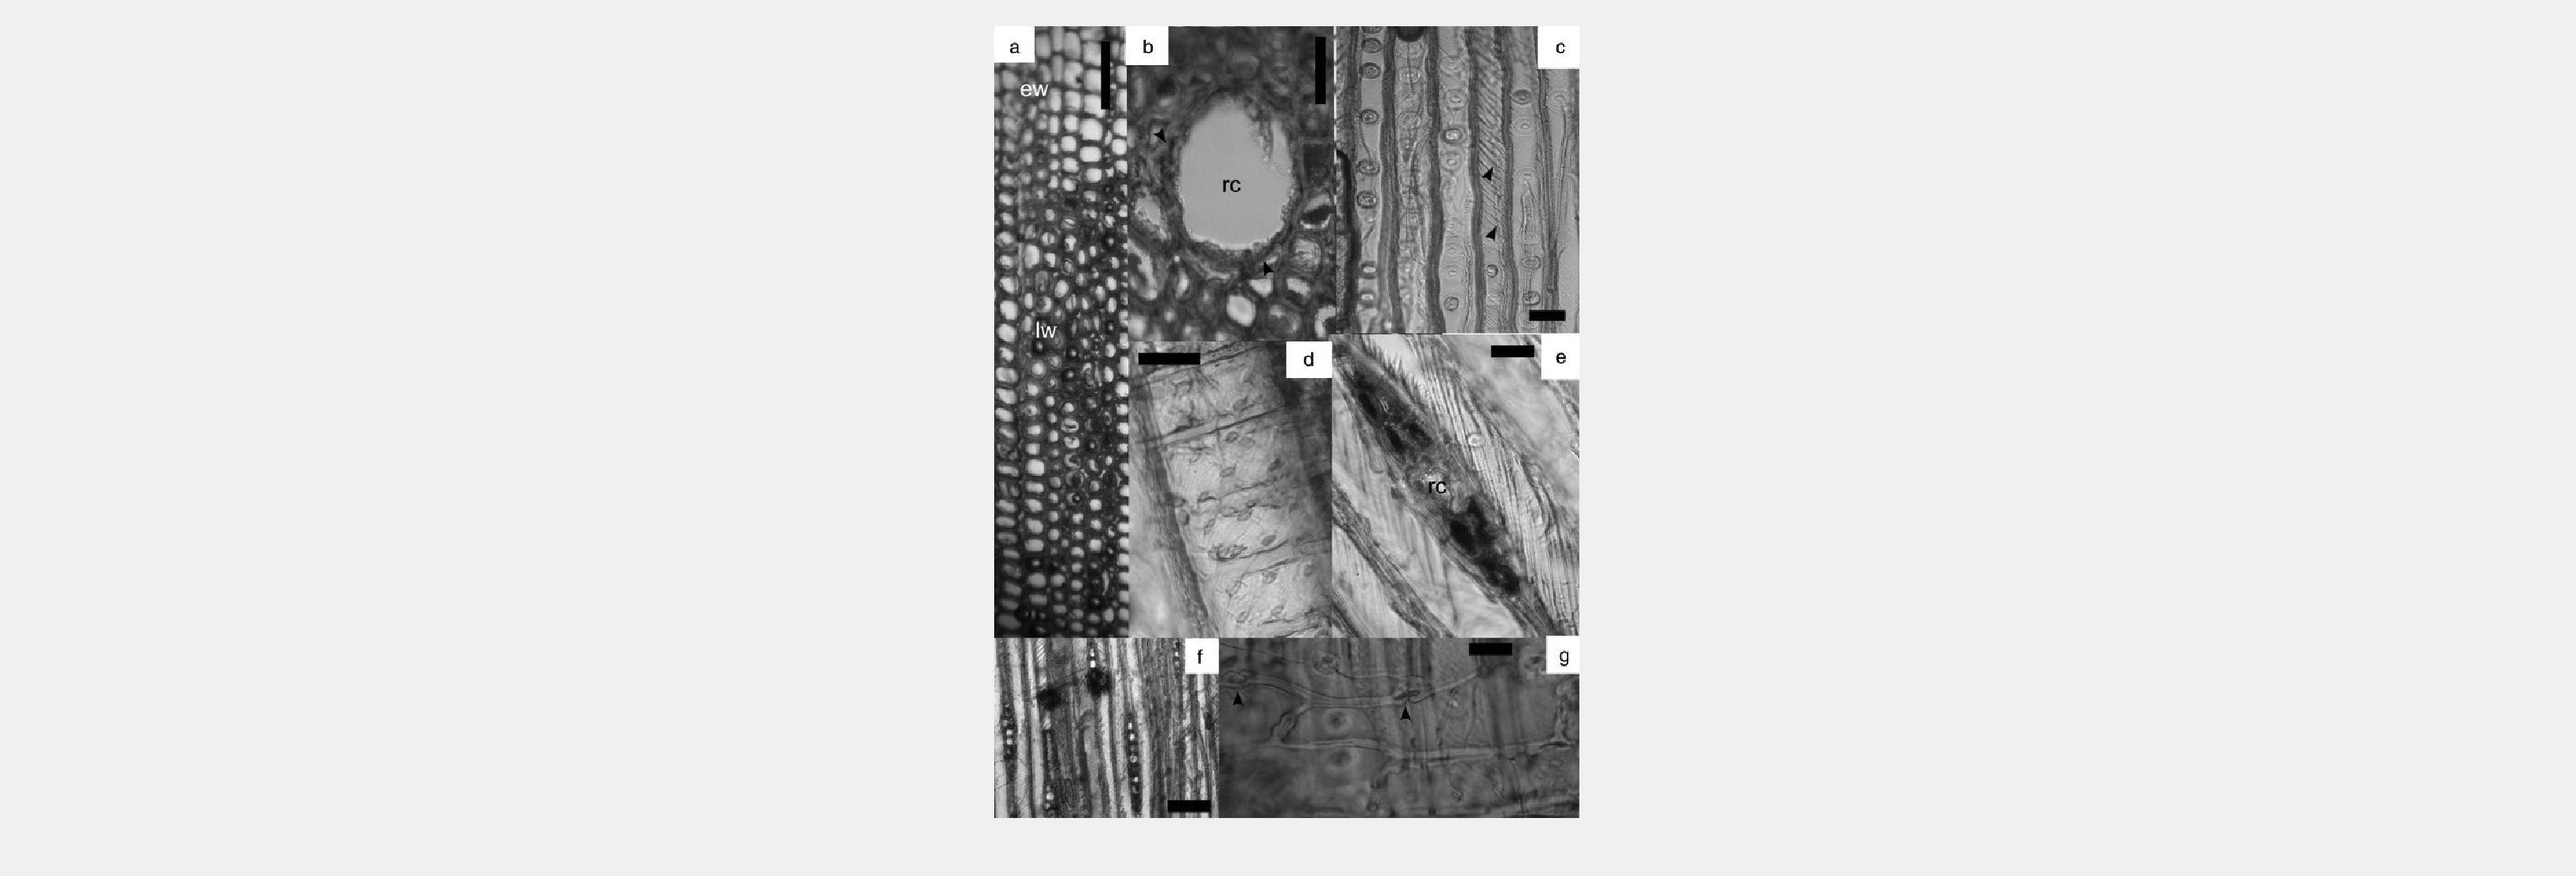

f = figure('visible', true);  % new figure in its own figure window
imshow('resin_canal.jpg')

Your resin canal image should open in a separate window.  Use the zoom and pan tools to get the resin canal in the centre of the image.  Try to get something like this.

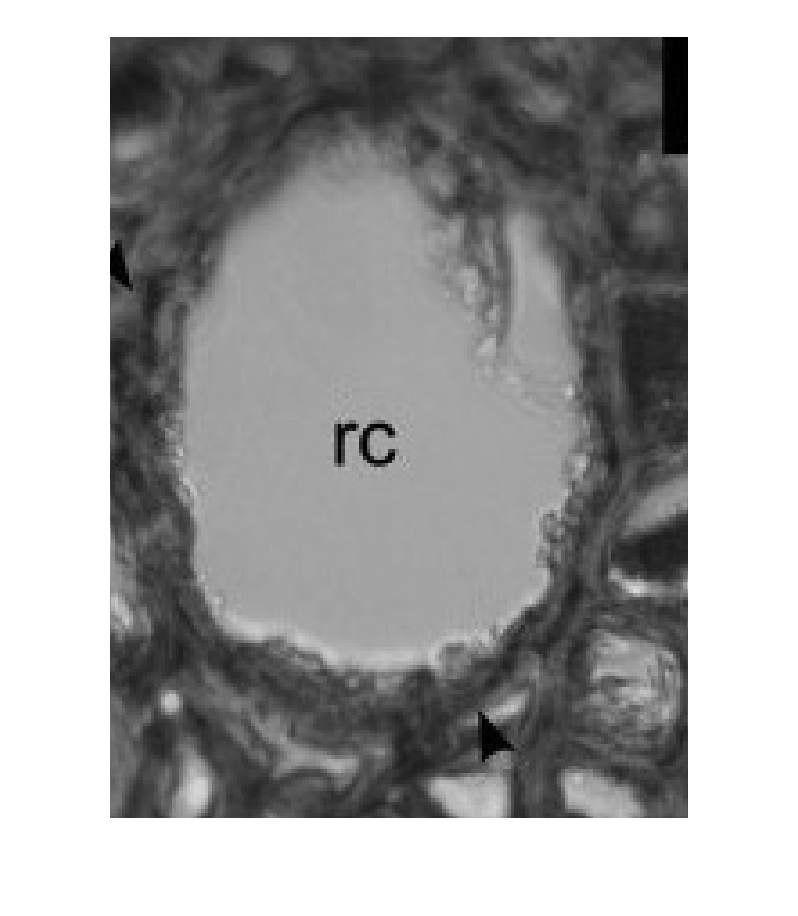

We are going to measure the area of the fossilised resin canal shown in section (b) of the image. Our method to compute the area is to create a *polygon* to approximate the boundary of the object using the `drawpolygon` command, then compute the area of the polygon using the `polyarea` command to.

First, we issue the `drawpolygon` command.  With this tool an editable, movable polygon may be created to approximate the boundary of the resin canal.

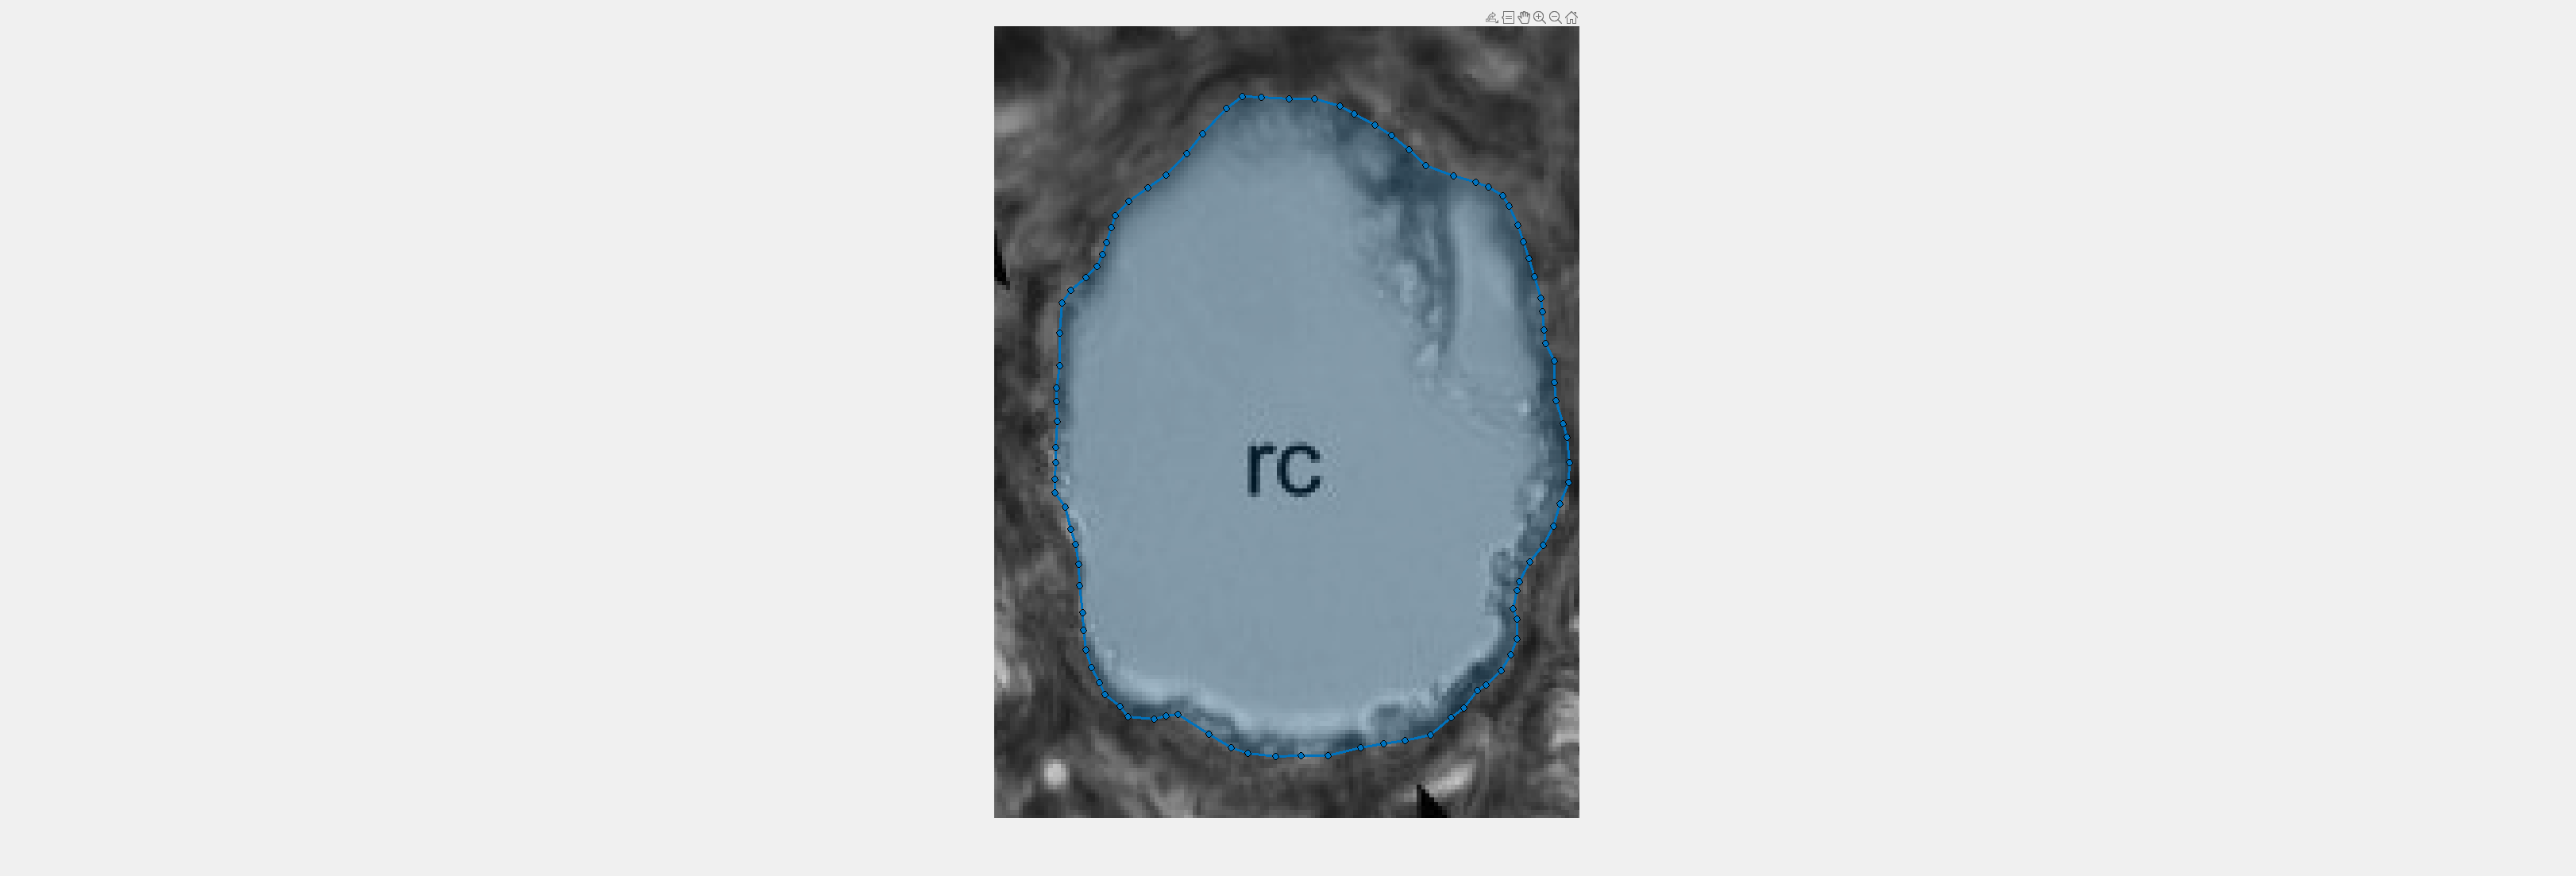

h =   Polygon with properties:

    Position: [94×2 double]
       Label: ''
       Color: [0 0.4470 0.7410]
      Parent: [1×1 Axes]
     Visible: on
    Selected: 0

  Show all properties


h = drawpolygon(f.CurrentAxes)  % draw on the current figure axes

The variable `h` we created here is a *handle* to the Polygon object.  We'll need it later to get the coordinates of the vertices.

Click around the edges of the resin canal in your figure window to draw a crude polygon.  Something like this.

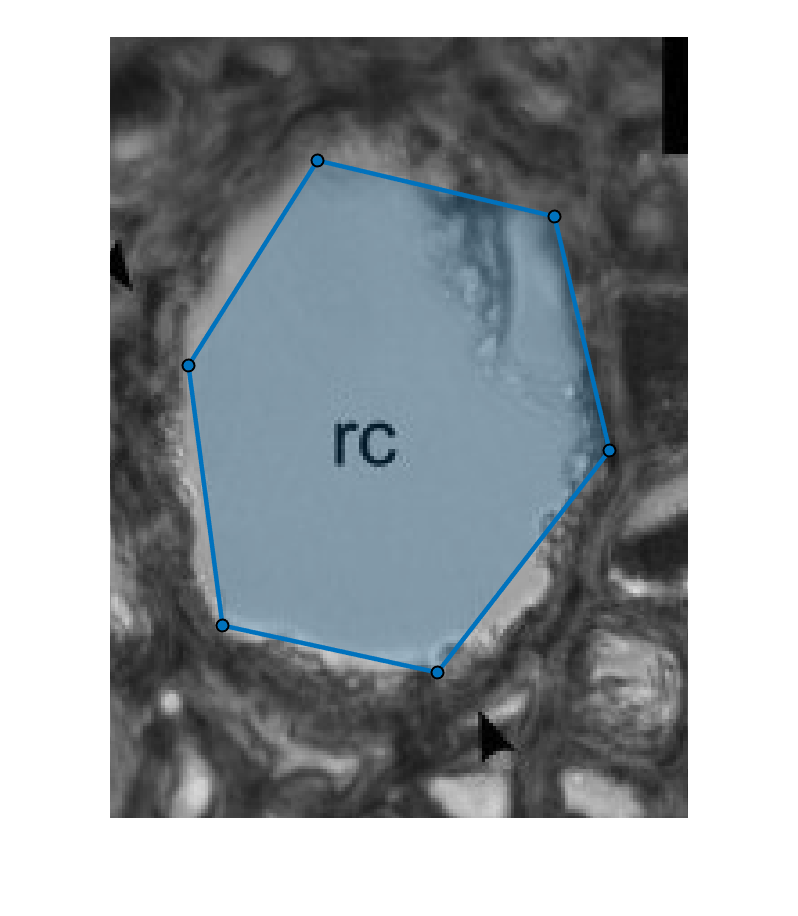

You can now add more vertices by double clicking anywhere on the perimeter, and you can drag existing vertices around to get a smoother polygon.  Aim for something like this.

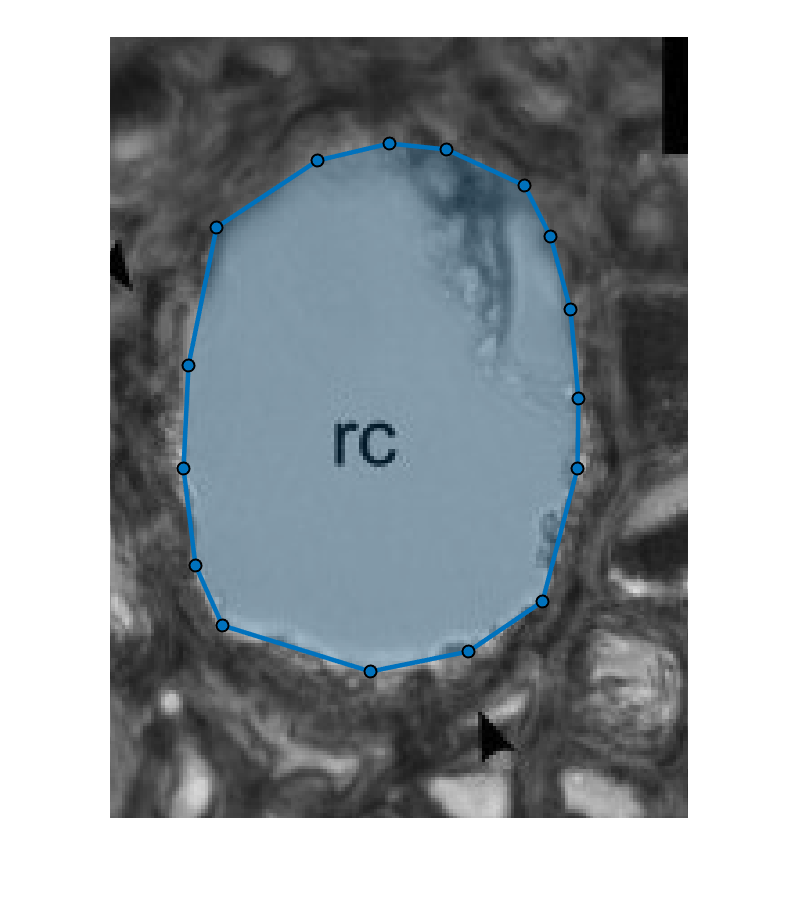

When you're happy with your polygon, you can get the coordinates of the vertices using the `Position` property:

coords = h.Position

coords =   221.5305   72.7335
  215.9047   78.7344
  212.1541   83.4226
  207.2784   88.4858
  202.9652   91.4863
  198.4646   94.6742
  195.2766   98.0497
  194.3390  100.8627
  193.2138  104.4257
  192.2762  107.2386


We can extract the `x` and `y` coordinates separately, from each column of `coords`.

x = coords(:,1)  % this means "all rows, 1st column" of coords

x =   221.5305
  215.9047
  212.1541
  207.2784
  202.9652
  198.4646
  195.2766
  194.3390
  193.2138
  192.2762


y = coords(:,2)  % this means "all rows, 2nd column" of coords

y =    72.7335
   78.7344
   83.4226
   88.4858
   91.4863
   94.6742
   98.0497
  100.8627
  104.4257
  107.2386


Now calculate the area of the polygon using `polyarea`**:**

area = polyarea(x, y)

area = 1.4853e+04

But wait, what are the *units* of this answer?  The coordinates we got are just MATLAB's figure coordinates (in pixels).  They don't have any physical meaning.

Fortunately, like all good scientific figures, this figure includes a *scale bar*.  This will allow us to convert to true physical values.

The scale bar is the vertical black rectangle in the top right corner of section (b) of the image.  In the paper, the figure has a caption explaining that *the scale bar represents 35 microns*.

Using the same technique as you did above, draw a polygon around the rectangle and use the returned coordinates to calculate its *length *(in pixels).  Alternatively, you could experiment with the `drawline` comand instead, to save having to make a polygon when really a length is all you want to know.  Or try it both ways for fun!

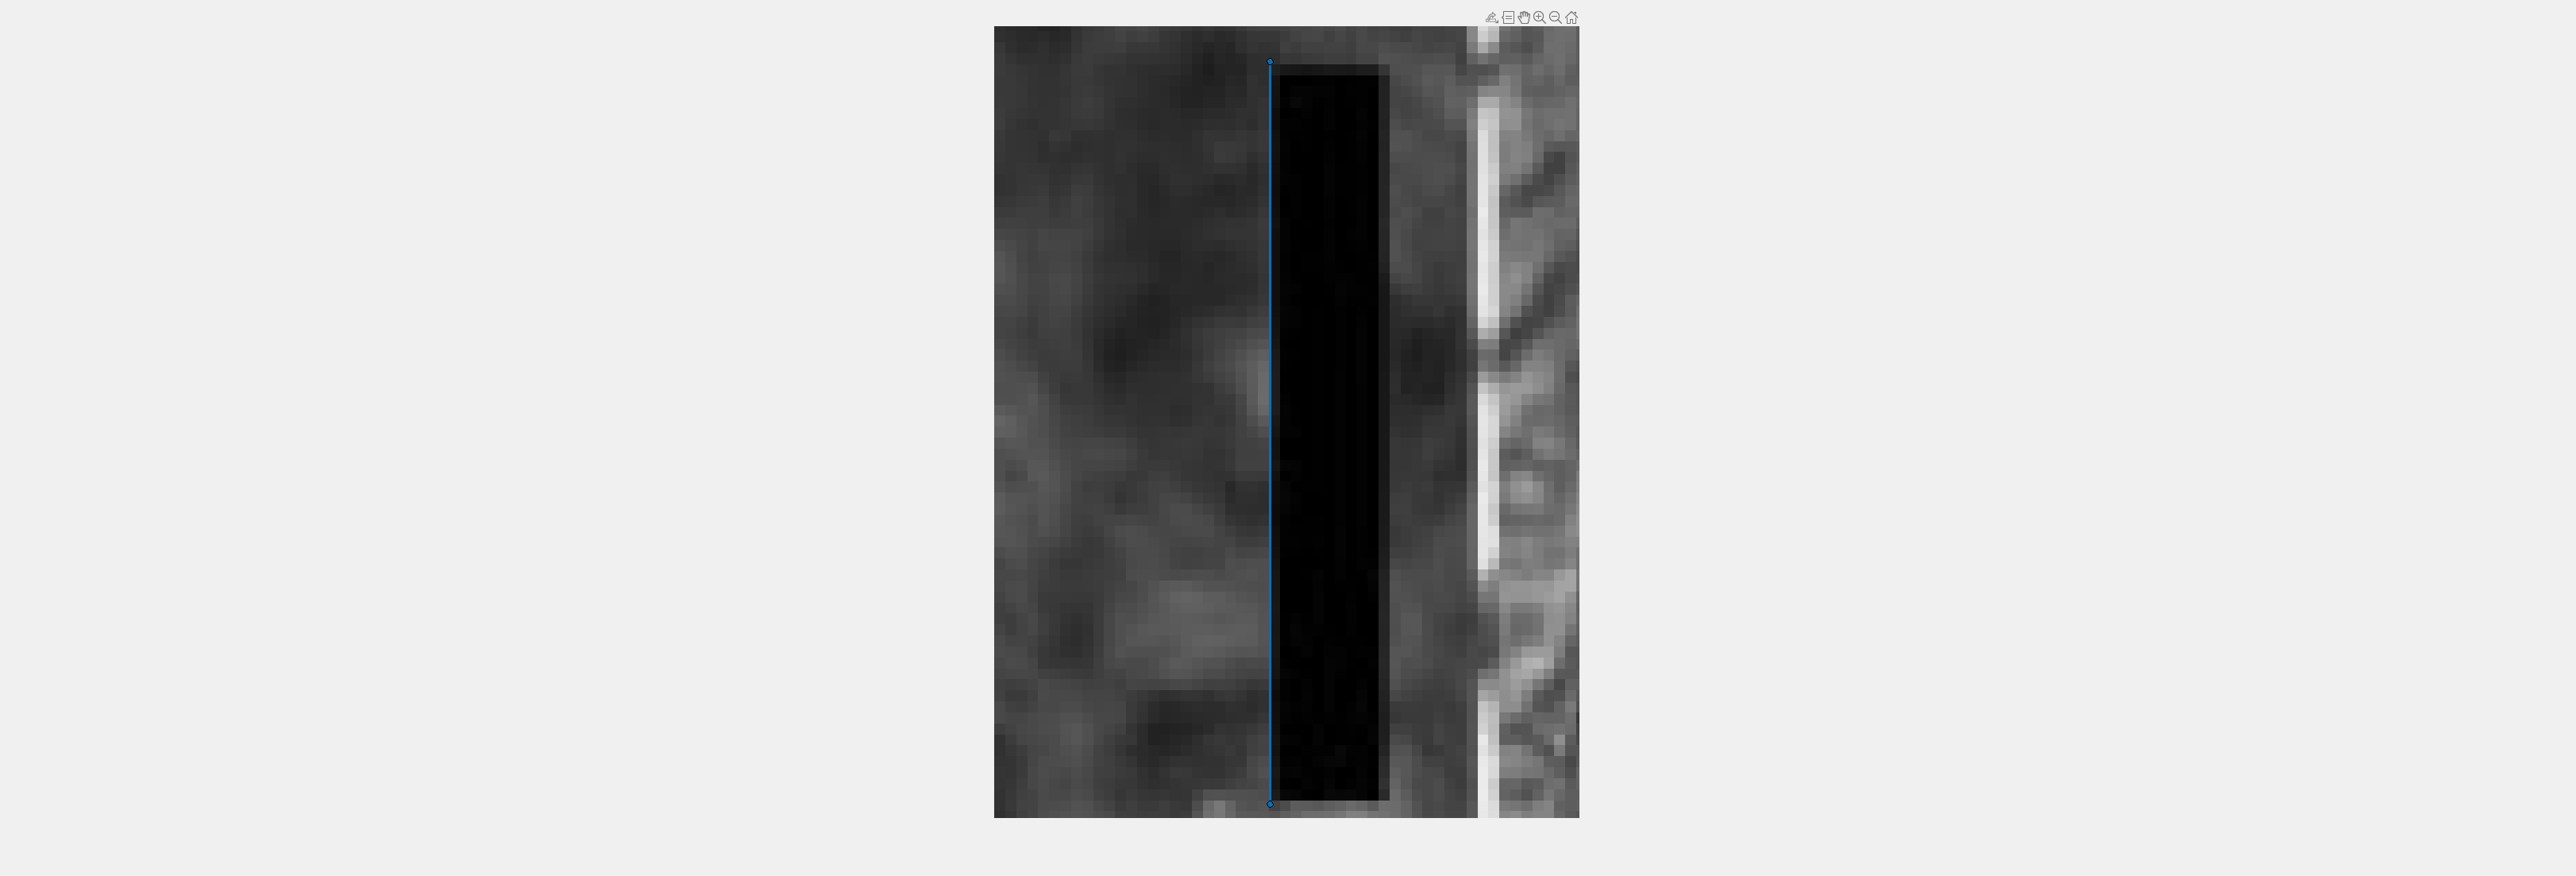

h2 =   Line with properties:

    Position: [2×2 double]
       Label: ''
       Color: [0 0.4470 0.7410]
      Parent: [1×1 Axes]
     Visible: on
    Selected: 0

  Show all properties


h2 = drawline(f.CurrentAxes)% h2 =     % use drawpolygon or drawline, you decide

coords = h2.Position

coords =   317.6156   10.2582
  317.6156   77.8587


Given that this length represents 35 microns, calculate a scaling factor `microns_per_unit_length`.

y2 = coords(:,2);
microns_per_unit_length = (y2(2) - y2(1))/35

microns_per_unit_length = 1.9314

Now use this scaling factor to convert your previous answer for the area in pixels to an area in *square microns*.

area = polyarea(x ./ microns_per_unit_length, y ./ microns_per_unit_length)

area = 3.9815e+03

You should get an answer around 3000-4000 square microns.

Just for fun, you can plot the polygon over the top of your image in a new figure using some *transparency*:

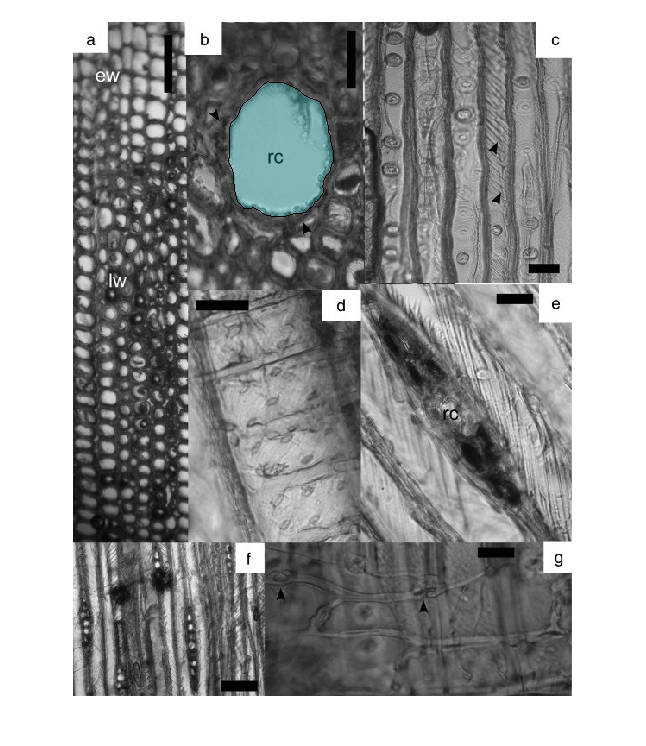

figure
imshow('resin_canal.jpg')
hold on
fill(h.Position(:,1), h.Position(:,2), 'c', 'FaceAlpha', 0.2)

You might like to experiment with different `'FaceAlpha'` values.  Here we used 0.2, but any value between 0 and 1 is allowed.  Smaller values mean more transparent.

**Well done on finishing this section**.  Now you can continue on to the exercises.

# Exercises

1. Use a `for` loop to *animate* the process of joining up each sporting venue with the origin, similar to the animation in the online lecture.

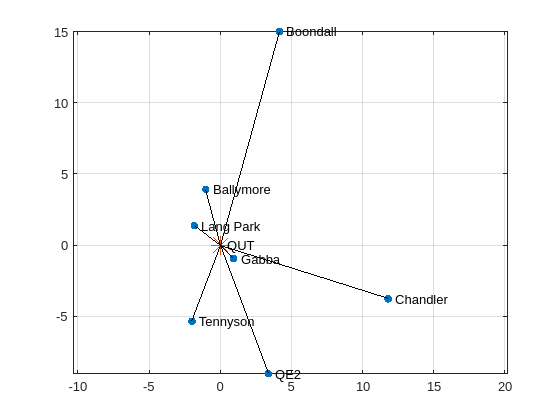

figure
venues_x = [-1.8265    0.9363   -1.0075    3.3735   -1.9844   11.7901    4.1628];
venues_y = [ 1.3581   -0.9557    3.9167   -9.0317   -5.3497   -3.7812   15.0184];
plot(venues_x, venues_y, ".", MarkerSize=14)
hold on
plot(0, 0, "*", MarkerSize=14)
axis equal
grid on
names = ["Lang Park", "Gabba", "Ballymore", "QE2", "Tennyson", "Chandler", "Boondall"];
text(venues_x, venues_y, "  " + names);
text(0, 0, "  QUT");
for i = 1:length(venues_x)
    plot([0, venues_x(i)], [0, venues_y(i)], 'k')
    java.lang.Thread.sleep(500)
    drawnow
end

2. Use `for` loops to animate the helices, corkscrews and rose curves you generated for IW1.

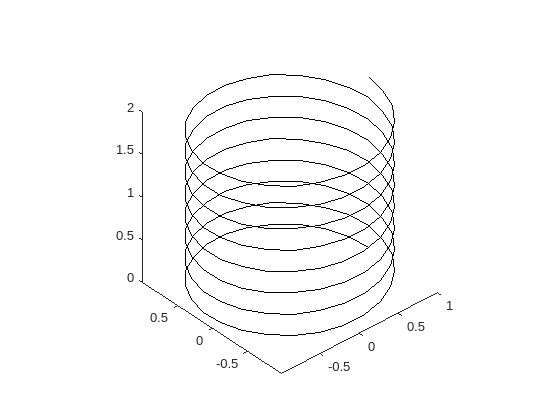

% Helices
figure
t = 0:0.01:2;
x = cos(8 * pi * t);
y = sin(8 * pi * t);
clear view
view([-41.700 35.700])
hold on
axis equal
for j = 1:length(t) - 1
    plot3([x(j), x(j + 1)], [y(j), y(j + 1)], [t(j), t(j + 1)], "k", MarkerSize=14)
    drawnow
end

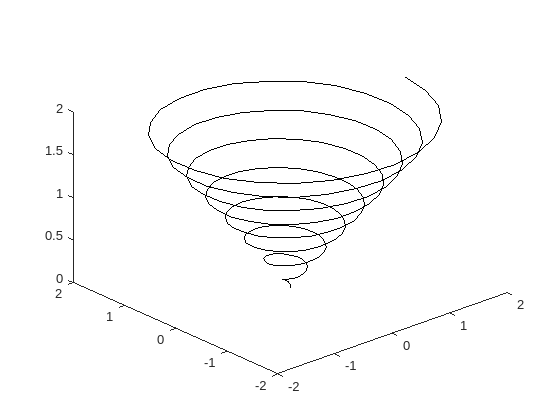


% Corkscrews
figure
t = 0:0.01:2;
x = cos(8 * pi * t) .* t;
y = sin(8 * pi * t) .* t;
clear view
view([-41.700 35.700])
hold on
for j = 1:length(t) - 1
    plot3([x(j), x(j + 1)], [y(j), y(j + 1)], [t(j), t(j + 1)], "k", MarkerSize=14)
    drawnow
end

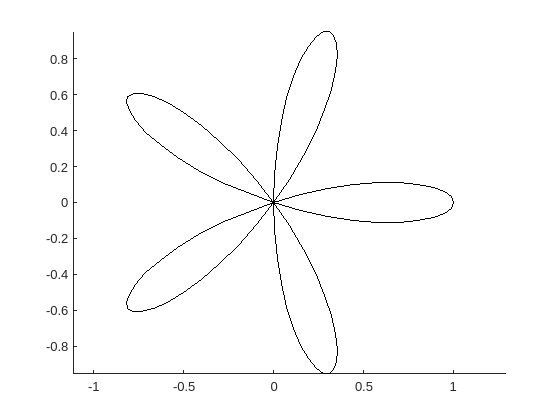


% Rose Curves
figure
t = 0:0.01:2;
k = 5;
x = cos(k * pi * t) .* cos(pi * t);
y = cos(k * pi * t) .* sin(pi * t);
hold on
axis equal
for j = 1:length(t) - 1
    plot([x(j), x(j + 1)], [y(j), y(j + 1)], "k", MarkerSize=14)
    drawnow
end

# Quiz

The Quiz is your assessment for this topic.  The link can be found on Canvas.  Follow the link to complete the Quiz.